clc, clearvars;

defaultSimLocation = 'D:\Creo_Simulations';
currentDateTime = char(datetime('now', 'Format','yyyy_MM_dd__hh_mm'));

loadType = 'new';
Tgoal = 150.0;

switch loadType
    case 'new'
        [~,creoResultsLocation] = uigetfile_extended('xlsx', defaultSimLocation);

        % Get a list of all .xlsx files in the designated location
        fileList = dir(fullfile(creoResultsLocation, '*.xlsx'));
        fileNames = {fileList.name}';

        % Names to remove
        namesToRemove = {''}; % Change these to the names you want to remove
        % Remove names matching the provided names
        filteredFileNames = setdiff(fileNames, namesToRemove);
        % Create a struct with fields as filenames' last characters after '_' without file extension
        S = struct();
        for i = 1:length(filteredFileNames)
            [~, name, ~] = fileparts(filteredFileNames{i});
            splittedFileName = split(name, '_');
            filedName = splittedFileName{end}; % Get the last character after '_'
            S.(filedName) = readtable(fullfile(creoResultsLocation, filteredFileNames{i}));
        end
        
        matFileName_ = split(creoResultsLocation, '\');
        matFileName = [matFileName_{end-1} '_' currentDateTime '.mat'];
        save(matFileName, 'S');
        sprintf('File %s was saved...', matFileName)
    case 'load'
        dirRes = dir('*.mat');
        if isempty(dirRes)
            error('No .mat files found.');
        end
        fileNames = {dirRes.name};

        [idx, ok] = listdlg( ...
            'PromptString', 'Select a MAT file:', ...
            'SelectionMode', 'single', ...
            'ListString', fileNames);

        selectedFile = fileNames{idx};
        disp(['Selected file: ', selectedFile]);
        load(selectedFile);
end

ans = 'File EXPC_COOLING_CONSTANT_TS_2026_01_28__12_31.mat was saved...'

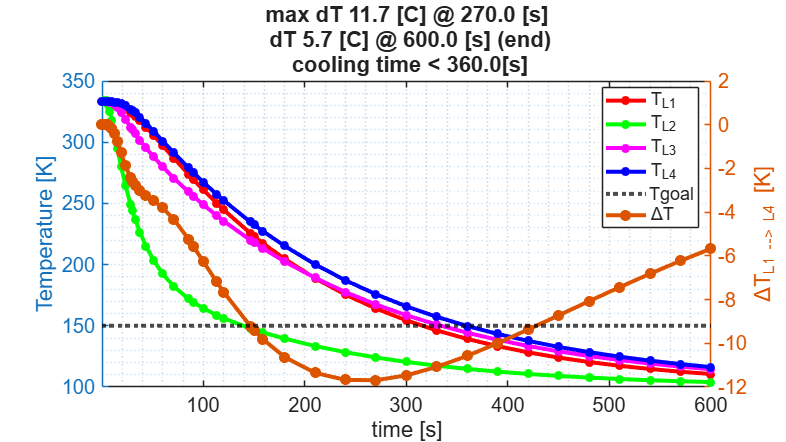

t = S.L1.Time;
T1 = S.L1.L_TEMP_PNT1;
T2 = S.L2.L_TEMP_PNT2;
T3 = S.L3.L_TEMP_PNT3;
T4 = S.L4.L_TEMP_PNT4;

dT_L1L4 = T1 - T4;
[dT_L1L4_max, indx] = max(abs(dT_L1L4));
t_dT_L1L4_max = t(indx);
dT_L1L4_end = abs(dT_L1L4(end));

indx1 = find(T1 < Tgoal, 1, 'first');
indx2 = find(T2 < Tgoal, 1, 'first');
indx3 = find(T3 < Tgoal, 1, 'first');
indx4 = find(T4 < Tgoal, 1, 'first');

tCooling = t(max([indx1, indx2, indx3, indx4]));

figure('Units','normalized', 'Position',[0 0 0.85 0.85])
yyaxis left
plot(t,  T1,'r-o' ,...
    'LineWidth', 3.0, 'Marker','.', 'MarkerSize',20.0,...
    'DisplayName','T_{L1}'); hold on;
plot(t, T2,'g-o' ,...
    'LineWidth', 3.0, 'Marker','.', 'MarkerSize',20.0,...
    'DisplayName','T_{L2}');
plot(t, T3,'m-o' ,...
    'LineWidth', 3.0, 'Marker','.', 'MarkerSize',20.0,...
    'DisplayName','T_{L3}');
plot(t, T4,'b-o' ,...
    'LineWidth', 3.0, 'Marker','.', 'MarkerSize',20.0,...
    'DisplayName','T_{L4}');
yline(Tgoal, 'k:', 'LineWidth', 3.0, 'DisplayName','Tgoal')
ylabel('Temperature [K]');
xlabel('time [s]');
legend('show', 'Location','best');
title(sprintf('max dT %.1f [C] @ %.1f [s]\n dT %.1f [C] @ %.1f [s] (end)\n cooling time < %.1f[s]',...
dT_L1L4_max, t_dT_L1L4_max, dT_L1L4_end,  t(end), tCooling));
set(gca, 'FontSize', 15);

yyaxis right
plot(t, dT_L1L4,...
    '-' , 'LineWidth', 3.0, 'Marker','.', 'MarkerSize',25.0, 'DisplayName','\DeltaT');
xlim([0.1 max(t)])
ylabel('\DeltaT_{L1 --> L4} [K]', 'Interpreter','tex');
grid minor